# Teste NEULERM_SED

15/04/2021  Arménio Correia   armenioc@isec.pt

13/05/2021  Paulo Gouveia    a2020121705.isec.pt

13/05/2021  Miguel Ferreira  a2020107016.isec.pt

13/05/2021  Pablo Amaral     a2020143935.isec.pt

syms u(t) v(t)

f =@(t,u,v) v;
g =@(t,u,v) -16*u;
a = 0;
b = 4;
n = 100;
u0 = 9;
v0 = 0;

eqns = [diff(u,t,1)==v,diff(v,t,1)==-16*u];
ci = [u(0)==u0,v(0)==v0];
[sExataU,sExataV] =dsolve(eqns,ci);

h = @(t) eval(vectorize(char(sExataU)));

[t,uEuler,~] = NEulerSED(f,g,a,b,n,u0,v0);
[~,uEulerM,~] = NEulerMSED(f,g,a,b,n,u0,v0);

uExata = h(t)

uExata =     9.0000    8.8850    8.5431    7.9830    7.2189    6.2704    5.1617    3.9211    2.5804    1.1738   -0.2628   -1.6927   -3.0793   -4.3873   -5.5833   -6.6365   -7.5203   -8.2119   -8.6938   -8.9536   -8.9847   -8.7862   -8.3633   -7.7267   -6.8928   -5.8828   -4.7225   -3.4416   -2.0727   -0.6509    0.7875    2.2058    3.5678    4.8386    5.9858    6.9801    7.7961    8.4129    8.8149    8.9916    8.9387    8.6574    8.1549    7.4442    6.5432    5.4752    4.2672    2.9503    1.5579    0.1258



erroEuler = abs(uExata-uEuler);
erroEulerM = abs(uExata-uEulerM);

array2table([t.',uExata.',uEuler.',uEulerM.',erroEuler.',erroEulerM.'],"VariableNames",{'t','Exata','Euler','Euler Melhorado','erroEuler','erroEulerM'})

ans = 101×6 table
     t       Exata      Euler     Euler Melhorado    erroEuler    erroEulerM
    ____    _______    _______    _______________    _________    __________

       0          9          9              9               0              0
    0.04      8.885          9         8.8848         0.11495     0.00024555
    0.08     8.5431     8.7696         8.5421         0.22648     0.00096964
    0.12      7.983     8.3088         7.9808         0.32585      0.0021351
    0.16     7.2189     7.6235         7.2152         0.40464      0.0036815
     0.2     6.2704     6.7255         6.2648         0.45513      0.0055275
    0.24     5.1617     5.6323         5.1541         0.47064      0.0075742
    0.28     3.9211      4.367         3.9114         0.44584      0.0097087
    0.3

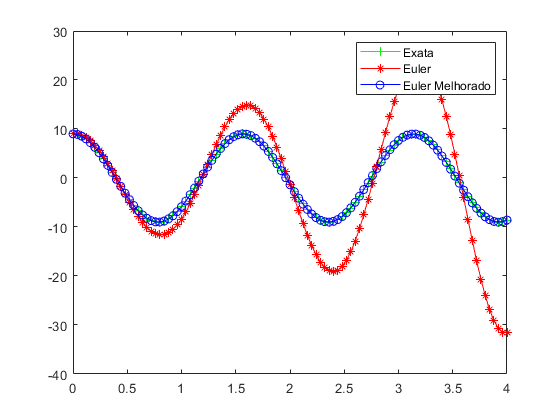


plot(t,uExata,"-g+")
hold on
plot(t,uEuler,"-r*")
plot(t,uEulerM,"-bo")
hold off
legend("Exata","Euler","Euler Melhorado")